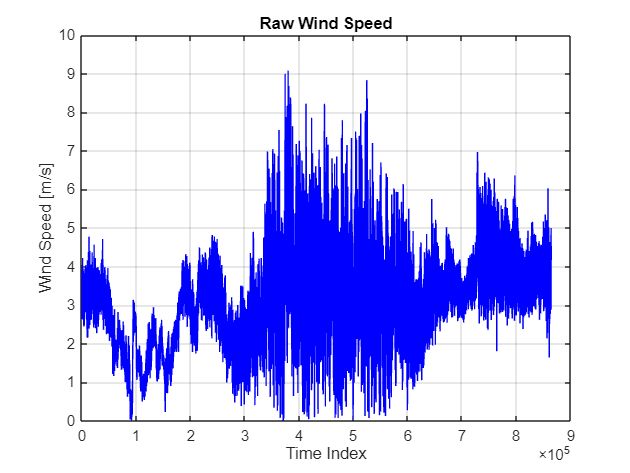

clear; close all;

%% === Step 1: Load and Clean Wind Data ===
A = importdata('31Oct2024.dat');
wind_speed = A.data(:,1);  % Assuming wind speed in column 1

% Remove NaNs and non-physical values
valid_idx = ~isnan(wind_speed) & wind_speed > 0;
wind_clean = wind_speed(valid_idx);

%% === Step 3: Plot Raw vs Cleaned and Statistics ===
figure;
plot(wind_clean, 'b'); hold on;

grid on;
xlabel('Time Index');
ylabel('Wind Speed [m/s]');
title('Raw Wind Speed');